Pre-Emphasis

[y,fs]=audioread("C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\audio_files\one.wav")

y =     0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002
    0.0002    0.0002


fs = 44100

length_of_signal=length(y)

length_of_signal = 112852

pre_emphasised=zeros(size(y))

pre_emphasised =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


N=length_of_signal

N = 112852

filter_coeff=[1,-0.95];

for i=2:N
    pre_emphasised(i)=y(i)*filter_coeff(1)+y(i-1)*filter_coeff(2);
end

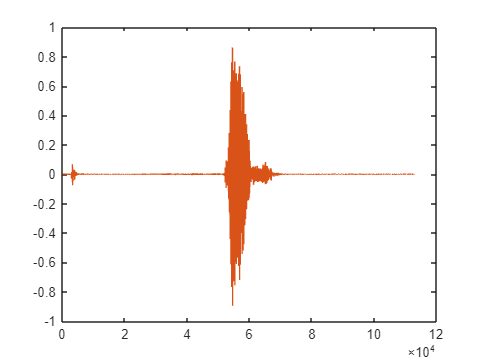

plot(y)

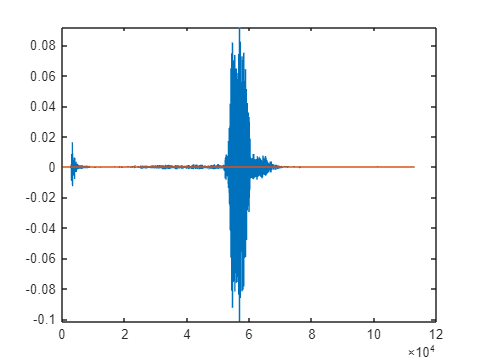

plot(pre_emphasised)

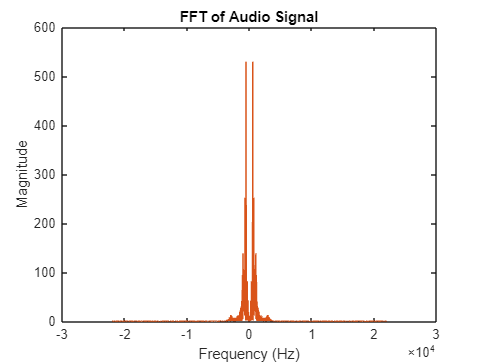

X = fft(y);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

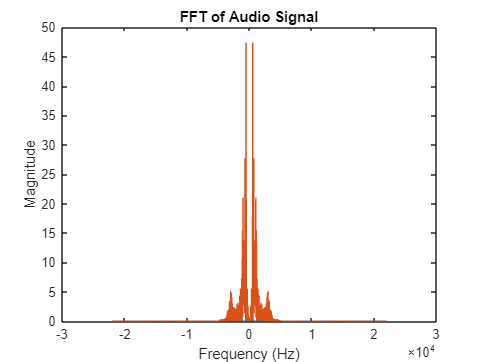


X = fft(pre_emphasised);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

sound(pre_emphasised,fs)

Noise-Gate

threshold=0.01

threshold = 0.0100

filtered_signal = pre_emphasised;
filtered_signal(abs(pre_emphasised) < threshold) = 0;

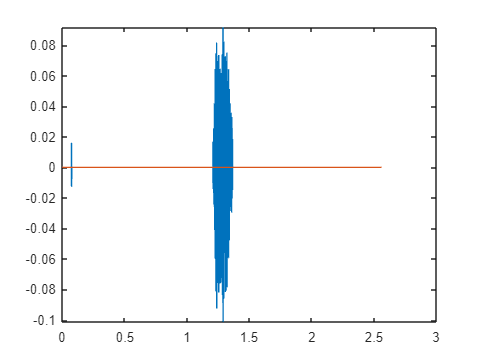

t = (0:length(y)-1) / fs;
plot(t,filtered_signal)

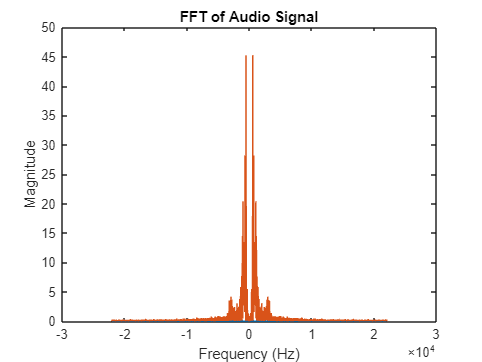


X = fft(filtered_signal);

% Calculate the frequency axis
f = linspace(-fs/2, fs/2, length(X));

% Plot the magnitude spectrum
figure;
plot(f, fftshift(abs(X)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of Audio Signal');

sound(filtered_signal,fs)

audiowrite('1.wav',y,fs)
audiowrite('2.wav',pre_emphasised,fs)
audiowrite('3.wav',filtered_signal,fs)

Zero-Allignment

audio=detrend(filtered_signal)

audio =     0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0
    0.0000         0


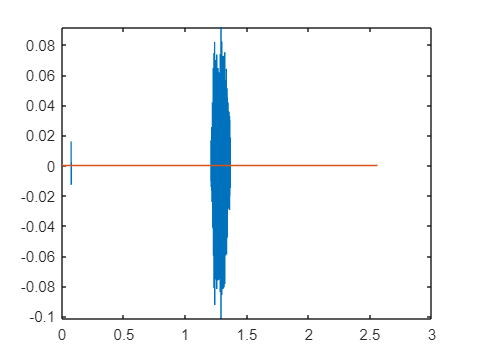

plot(t,audio)

% Specify the input audio file
inputFile = 'one.wav';

% Read the audio file
[x, fs] = audioread(inputFile);

% Specify the duration of each chunk in seconds
chunkDuration = 1;  % adjust this according to your needs

% Calculate the number of samples in each chunk
chunkSize = round(chunkDuration * fs);

% Calculate the number of chunks
numChunks = ceil(length(x) / chunkSize);

% Loop through the audio and write each chunk to a separate file
for i = 1:numChunks
    % Determine the start and end indices for the current chunk
    startIndex = (i - 1) * chunkSize + 1;
    endIndex = min(i * chunkSize, length(x));
    
    % Extract the current chunk
    currentChunk = x(startIndex:endIndex);
    
    % Create a filename for the current chunk (e.g., chunk1.wav, chunk2.wav, etc.)
    outputFileName = sprintf('chunk%d.wav', i);
    
    % Write the current chunk to a separate file
    audiowrite(outputFileName, currentChunk, fs);
end

% Specify the input audio file
inputFile = 'one.wav';

% Read the audio file
[x, fs] = audioread(inputFile);

% Define framing parameters
frameDurationMin = 1;  % 20 milliseconds
frameDurationMax = 2;  % 30 milliseconds
overlapRatio = 1.0;  
frameLength = 256;

% Convert frame durations to samples
frameSizeMin = round(frameDurationMin * fs);
frameSizeMax = round(frameDurationMax * fs);

% Calculate overlap size
overlapSize = round(frameLength * overlapRatio);

% Reshape the audio signal into a column vector
x = x(:);

% Generate frames with overlap
frames = buffer(x, frameSizeMax, overlapSize, 'nodelay');

% Loop through the frames and process them as needed
numFrames = size(frames, 2);
for i = 1:numFrames
    % Extract the current frame (consider using frameSizeMin for analysis)
    currentFrame = frames(:, i);
    N=length(currentFrame);
    n=(0:N-1);
    W=0.54-0.46*cos(2*pi*n/(N-1));
    windowed=currentFrame.*W;
    t_frame = ((i - 1) * overlapSize + 1 : (i - 1) * overlapSize + frameSizeMax) / fs;
    %plot(t_frame, windowed);

    % Process the current frame (replace this with your processing code)
    % For example, you can perform some analysis or apply a specific operation
    
    % Create a filename for the current frame (e.g., frame1.wav, frame2.wav, etc.)
    outputFileName = sprintf('frame%d.wav', i);
    
    % Write the current frame to a separate file
    %audiowrite(outputFileName, currentFrame, fs);
end

Requested 88200x88200 (58.0GB) array exceeds maximum array size preference (7.8GB). This might cause MATLAB to become unresponsive.

Related documentation

W(n)=0.54-0.46*cos(2*pi*n/(N-1))